# Figure 1: Superfine Contour

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
addpath([CurrentFolder '/HPCData'])


load('Figure1_Data_S_EE=0.024_S_II=0.12_S_Elgn=0.060_7D_HPC_S_IlgnInd3_rI_L6Ind3.mat','ContourData_7D')

S_EEtest = [0.020 0.024 0.028];
S_IItest = [0.06  0.09  0.12  0.15  0.18];
S_ElgnInd = 3;
S_IlgnInd = 3; % $(seq 2 4)
rI_L6Ind = 3;  % 3 6
S_EEInd = 2;
S_IIInd = 3;

S_EE = S_EEtest(S_EEInd);
S_Elgntest = [1.5 2 2.5 3.0]*S_EE;
S_Elgn=S_Elgntest(S_ElgnInd);

S_II = S_IItest(S_IIInd);
S_Ilgntest = [1 1.5 2 2.5]*S_Elgn;
        S_Ilgn = S_Ilgntest(S_IlgnInd);

## Fine Contours

CurrentBlowup = squeeze(ContourData_7D.FailIndi(:,:)); CurrentBlowup(1:35,1:283) = 1; CurrentBlowup = logical(CurrentBlowup);
Currentsteady = squeeze(ContourData_7D.ConvIndi(:,:)); Currentsteady(1:35,1:283) = true;

CurrentBlowupModi = false(size(CurrentBlowup));
CurrentsteadyModi =  true(size(CurrentBlowup));
% first modify Blowup map
for ColInd = 1:size(CurrentBlowup,2)
    BUInds = find(CurrentBlowup(:,ColInd));
    USInds = find(~Currentsteady(:,ColInd));
    
    CurrentBlowupModi(1:BUInds(end-1),ColInd) = true;
    CurrentsteadyModi(USInds(1):USInds(end),ColInd) = false;
end

% figure('Name','BlowStea')
% subplot 121
% imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,CurrentBlowupModi)
% set(gca,'YDir','Normal')
% subplot 122
% imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,CurrentsteadyModi)
% set(gca,'YDir','Normal')

% Merge the blowup and unsteady map
BlowSteadShow = double(CurrentBlowupModi)+0.5*double(~CurrentsteadyModi);
BlowSteadShow(BlowSteadShow>1) = 0.5;
for ColInd = 1:size(BlowSteadShow,2)
    
    BUInds = find(BlowSteadShow(:,ColInd) == 1);
    USInds = find(BlowSteadShow(:,ColInd) == 0.5);
    
    if isempty(USInds)
        continue
    end
    BUInds(BUInds<=max(USInds)) = [];
    
    if isempty(BUInds)
        continue
    end
    
    BlowSteadShow(BUInds(1):BUInds(end),ColInd) = 0.5;
end
 
Fig1 = figure('Name','Figure1','units','normalized','outerposition',[0 0 0.95 0.7]);
%convolution mat
KerSize = 8;
ConvMat = 1/KerSize^2*ones(KerSize);
%cmap = [1,1,1; 0.5, 0.5, 0.5; 0, 0, 0];
BlowSteadShow = cat(3,1-BlowSteadShow,1-BlowSteadShow,1-BlowSteadShow);


### The first panel


subplot 121
hold all
image(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,BlowSteadShow)
set(gca,'YDir','Normal')
%colormap(cmap);

CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,: ));
CurrentFrE = FrRateModify(CurrentFrE, 1,CurrentBlowupModi,CurrentsteadyModi);
[C1r,h1r]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrE,[1:8 ],'ShowText','off','color',1-[0,1,1]*0.25);

CurrentFrESm = FrRateModify(CurrentFrE, ConvMat,CurrentBlowupModi,CurrentsteadyModi);
[C1,h1]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrESm,[1:8 ],'ShowText','off','color','r');
h1.LineWidth = 0.1;

[C1k,h1k]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrESm,[3 5 ],'ShowText','off','color','k','linestyle','--');
h1k.LineWidth = 3;  
%h1k.LineWidth = 0.1;
%clabel(C1,h1,'FontSize',8,'Color','k')
%clabel(C1,h1,'FontSize',12,'Color',[0.5 0 0],'labelspacing',3700)

CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,: ));
CurrentFrI = FrRateModify(CurrentFrI, 1,CurrentBlowupModi,CurrentsteadyModi);
[C2r,h2r]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrI,[6:3:27],'ShowText','off','color',1-[1,1,0]*0.25);

CurrentFrISm = FrRateModify(CurrentFrI, ConvMat,CurrentBlowupModi,CurrentsteadyModi);
[C2,h2]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrISm,[6:3:27],'ShowText','off','color','b');
h2.LineWidth = 0.1; 

[C2k,h2k]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                 CurrentFrISm./CurrentFrESm,[3 4.25 ],'ShowText','off','color','k','linestyle','--');
h2k.LineWidth = 3;               
%clabel(C2,h2,'FontSize',8,'Color','k')
%clabel(C2,h2,'FontSize',12,'Color',[0 0 0.5],'labelspacing',3700)
clabel(C1,'manual','FontSize',12,'Color',[0.5 0 0])

 
    请稍候...
 
   仔细选择要用于标记的等高线。
   完成后，当图形窗口为活动窗口时，请按 Return 键。


clabel(C2,'manual','FontSize',12,'Color',[0 0 0.5])

 
    请稍候...
 
   仔细选择要用于标记的等高线。
   完成后，当图形窗口为活动窗口时，请按 Return 键。



xlabel('S_{IE}/S_{II}');ylabel('S_{EI}/S_{EE}')
hold off
axis square

title(sprintf('S_{EE}=%.3f; S_{II}=%.3f\nS_{Elgn}=%.3f; S_{Ilgn}=%.3f',...
               S_EE,        S_II,        S_Elgn,        S_Ilgn))


### The second panel

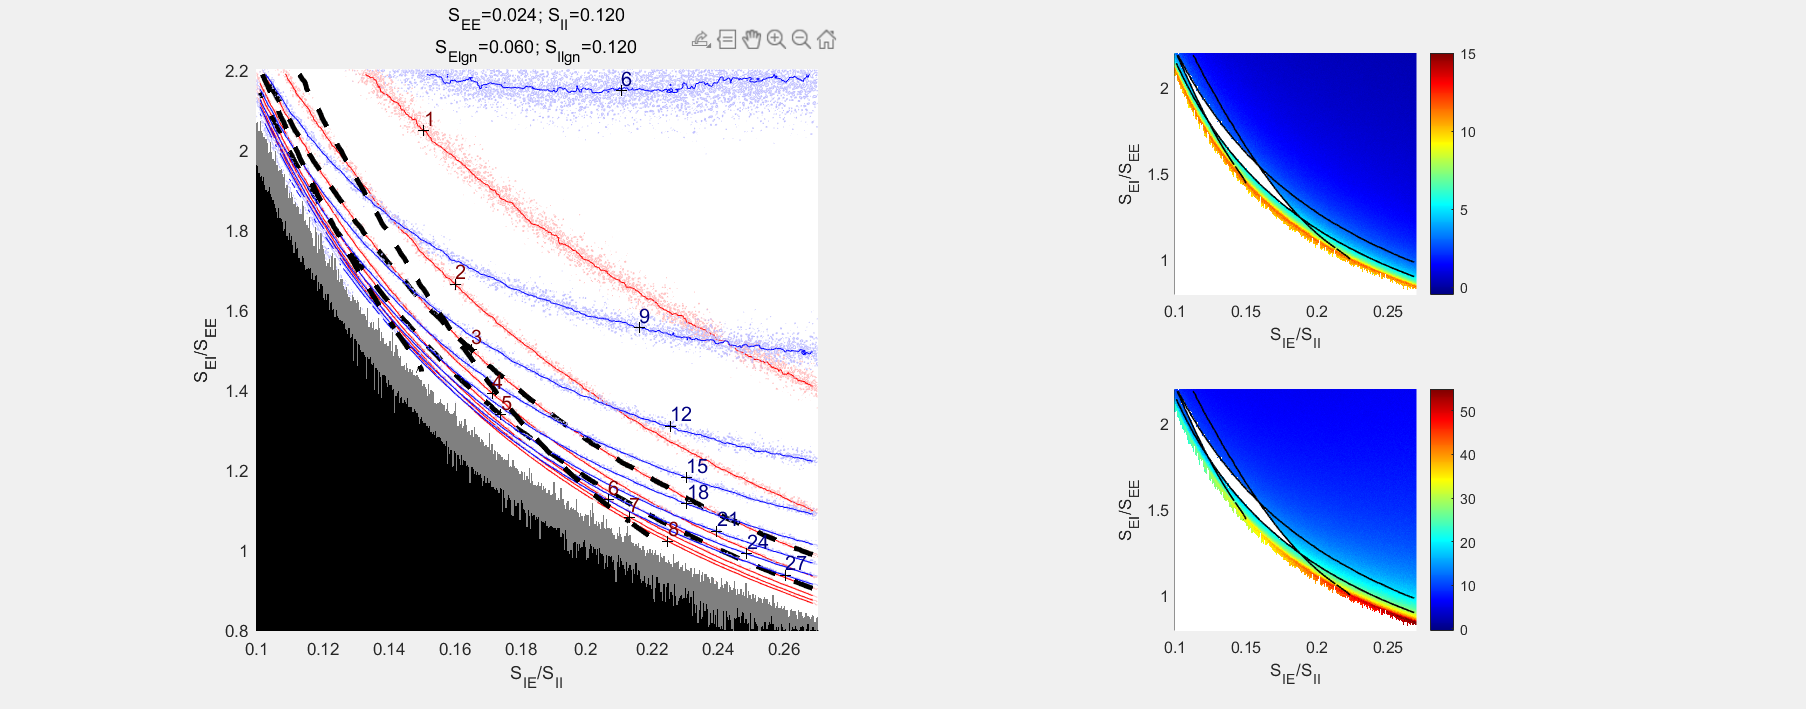

ax3 = subplot(2,2,2);
hold on
CurrentFrEShow = CurrentFrE;
CurrentFrEShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
           CurrentFrI./CurrentFrE    >=3 & ...
           CurrentFrI./CurrentFrE    <=4.25) = nan;
imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrEShow)
set(gca,'YDir','normal')
cmap = [1,1,1; jet];
colormap(gca, cmap); colorbar; caxis([-0.5 15])

[C1s,h1s]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrESm,[3 5],'ShowText','off','color','k');
h1s.LineWidth = 1;  
[C2s,h2s]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrISm./CurrentFrESm,[3 4.25],'ShowText','off','color','k');
h2s.LineWidth = 1; 
hold off
xlabel('S_{IE}/S_{II}');ylabel('S_{EI}/S_{EE}')
axis square
title('FrE')

ax4 = subplot(2,2,4);
hold on
CurrentFrIShow = CurrentFrI;
CurrentFrIShow(CurrentFrE>=3 & CurrentFrE<=5 & ...
           CurrentFrI./CurrentFrE    >=3 & ...
           CurrentFrI./CurrentFrE    <=4.25) = nan;
imagesc(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE, CurrentFrIShow)
set(gca,'YDir','normal')
cmap = [1,1,1; jet];
colormap(gca, cmap); colorbar; caxis([-0.5 55])

[C3s,h3s]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrESm,[3 5],'ShowText','off','color','k');
h3s.LineWidth = 1;  
[C4s,h4s]= contour(ContourData_7D.S_IEtest/S_II,ContourData_7D.S_EItest/S_EE,...
                     CurrentFrISm./CurrentFrESm,[3 4.25],'ShowText','off','color','k');
h4s.LineWidth = 1; 
hold off
xlabel('S_{IE}/S_{II}');ylabel('S_{EI}/S_{EE}')
axis square

title('FrI')

Save figures

Paperpath = [CurrentFolder '\Figure for Paper\'];
FigName1 = 'Figure1';
savefig(Fig1,[Paperpath FigName1 '.fig']);

Print Figs

Fig1.PaperUnits = 'centimeters';
Fig1.PaperSize = [42,15];
Fig1.PaperOrientation = "landscape";
exportgraphics(Fig1,[Paperpath FigName1 '.pdf'],'Resolution',900)